## **Calculus I**

### [**Hiroyuki Chihara**](https://fiomfd.github.io/)** (University of the Ryukyus, Okinawa Island, Japan)**

- Differentiability

- Convergence of Taylor series

- Convergence of Riemann sums

### 1. Differentiability

Let $f(x)$ be a function on an inverval $I$, and fix an arbitrary point $\bigl(a,f(a)\bigr)$ on the graph $\Gamma(f):=\{(x,f(x)) : x \in I\}$ of $f$. We consider all the lines passing trough $\bigl(a,f(a)\bigr)$, that is, we deal with a line $y=g(x):=f(a)+\beta(x-a)$ for all $\beta\in\mathbb{R}$. Strictly speaking we do not sonsider the vertical line $x=a$.  We observe the difference $f(x)-g(x)$ as $x \rightarrow a$. 

### 1-1. Preliminaries

close;
p =1.8

p = 1.8000

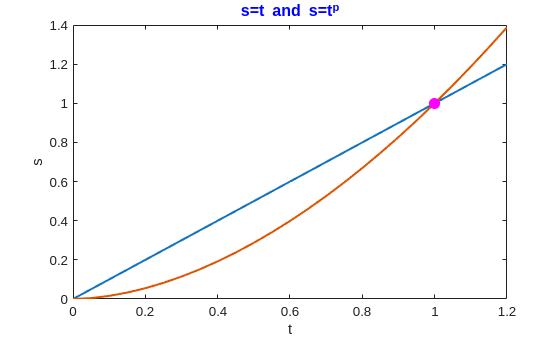

t0 = 0:0.05:1.2;
s0 = t0;
tp0 = t0.^p;

figure;
plot(t0,s0,t0,tp0,'LineWidth',1.5)
   ylim([0 1.4])
   xlim([0 1.2])
   title('s=t and s=t^p','Color','blue','FontSize',12)
   xlabel('t')
   ylabel('s')
   hold on
scatter([1],[1],70,'filled','magenta');

### 1-2. $f(x)=x^2$

If we set 


$$g(x):=f(a)+\beta(x-a)=a^2+\beta(x-a),$$


then we have 


$$\begin{array}{rcl}
f(x) - g(x) 
&=& 
x^2 -a^2 -\beta(x-a)
\\
&=& 
(x+a)(x-a) - \beta(x-a)
\\ 
&=& 
(x+a-\beta)(x-a)
\\
&=&
(2a-\beta)(x-a)+(x-a)^2.
\end{array}$$


Set $h(x)=a^2+2a(x-a)$, which is $g(x)$ with the special value $\beta=2a$. Then we have 


$$R(x):=
f(x)-h(x)=(x-a)^2,$$


which shows that $f(x) - h(x)$ goes to $0$ faster than $x-a$ and $f(x) - g(x)$ for all $\beta{\ne}2a$. 

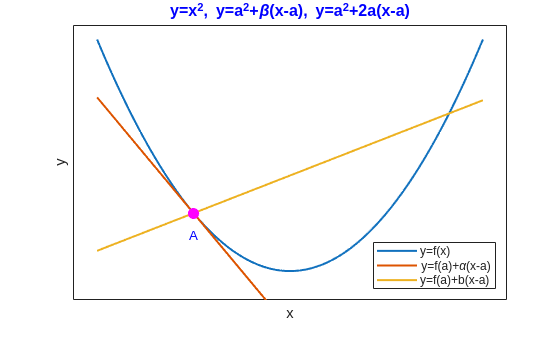

close;
a =-2; b =1.3;
p0=zeros(1,1);
q0=zeros(1,1);
p0(1,1)=a;
q0(1,1)=a^2;

x0 = -4:0.05:4;
f0=x0.^2;
g0=2*a*x0-a^2;
h0=b*x0-a*b+a^2;

f11=figure;
Y1=plot(x0,f0,x0,g0,x0,h0,'LineWidth',1.5);
   ylim([-2 17])
   xlim([-4.5 4.5])
   title('y=x^2, y=a^2+\beta(x-a), y=a^2+2a(x-a)','Color','blue','FontSize',12)
   text(a-0.1,a^2-1.5,'A','Color','blue','FontSize',10) 
   xlabel('x')
   xticks([])
   ylabel('y')
   yticks([])
hold on
   sz0=70;
Y2=scatter(p0,q0,sz0,'filled','magenta');
hold off
legend([Y1],{'y=f(x)','y=f(a)+{\alpha}(x-a)','y=f(a)+b(x-a)'},'Location','southeast')

%set(gcf,'Position',[200,200,350,280]);

### 1-3. $f(x)=|x|, a=0$

If we set


$$g(x)=f(0)+\beta(x-0)=\beta{x},$$


then we have 


$$f(x)-g(x)=-(\beta-1)x \quad (x \geq 0),
\qquad
f(x)-g(x)=-(\beta+1)x \quad (x<0).$$


$f(x) - g(x)$ can never go to $0$ as $x \rightarrow 0$ faster that $x$ for any $\beta \in \mathbb{R}$ since at least one of $\beta\pm1$ is not zero. 

### 1-4. Definition of differentiability

Suppose that a function $f(x)$ は $x=a$ is defined on an inverval $(a-\delta,a+\delta)$ near $x=a$. 

We say that $f(x)$ is differentiable at $x=a$ if exist  

- a constant $\alpha \in \mathbb{R}$

- a function $R(x)$ defined near $x=a$

such that 


$$f(x)=f(a)+\alpha(x-a)+R(x), 
\qquad
\frac{R(x)}{x-a} \rightarrow 0 
\quad
(x \rightarrow a).$$


In this case, the constant $\alpha$ is said to be the differential coefficient of $f(x)$ at $x=a$, and denoted by  


$$\frac{df}{dx}(a), \quad f^\prime(a).$$


Moreover the line passing through the point $\bigl(a,f(a)\bigr)$ with the slope $\alpha=f^\prime(a)$ 


$$y=f(a)+f^\prime(a)(x-a)$$


is said to be the tangent line of the graph $\Gamma(f)$ of $f$ at $\bigl(a,f(a)\bigr)$. 

Roughly speaking, we say that $f(x)$ is differentiable at $x=a$ if there exists an unique tangent line of $\Gamma(f)$ at $\bigl(a,f(a)\bigr)$. 

### 1-5. Theorem (Characterization of differentiability)

The following conditions are mutually equivalent:

- A function $f(x)$ is differentiable at $x=a$. 

- There exists $\alpha \in \mathbb{R}$ such that $\frac{f(x)-f(a)}{x-a} 
\rightarrow \alpha
\quad
(x \rightarrow a).$

### 2. Taylor's Theorem and Taylor Expansion

Taylor's theorem says that if $f(x)$ is $C^\infty$ near $x=a$ then for any $N=1,2,3,\dots,$ then


$$f(x)
=
\sum_{n=0}^{N-1}
\frac{f^{(n)}(a)}{n!}
(x-a)^n
+
R_N(x),$$



$$R_N(x)
=
\frac{f^{(N)}\bigl(\theta{x}+(1-\theta)a\bigr)}{N!}(x-a)^N
=
\frac{(x-a)^N}{(N-1)!}
\int_0^1
(1-t)^{N-1}
f\bigl(tx+(1-t)a)
dt,$$


where $\theta=\theta(x,a,N)\in(0,1)$ is a constant depending on $x$, $a$ and $N$. 

For **some** smooth function $f$ and **some** $x$, we have 


$$f(x)
-
\sum_{n=0}^{N-1}
\frac{f^{(n)}(a)}{n!}
(x-a)^n
=
R_N(x) \rightarrow 0 \quad\text{as}\quad N\rightarrow\infty.$$


In this case it is well-known that there exists $\rho\in(0,\infty]$ such that 


$$f(x)=
\sum_{n=0}^\infty
\frac{f^{(n)}(a)}{n!}
(x-a)^n,
\quad
x\in(a-\rho,a+\rho).$$


The right hand side of the above is said to be the Taylor series or the Taylor expansion of $f(x)$ at center $x=a$ with convergence radius $\rho$.

### Example: $\sin{x}$


$$\sin{x}=\sum_{k=0}^\infty\frac{(-1)^kx^{2k+1}}{(2k+1)!}, \quad x\in\mathbb{R}.$$


For any $R>0$, 


$$\max_{x\in[-R,R]}
\left|
\sin{x}
-
\sum_{k=0}^K
\frac{(-1)^kx^{2k+1}}{(2k+1)!}
\right|
\rightarrow 0 \quad (K\rightarrow\infty).$$


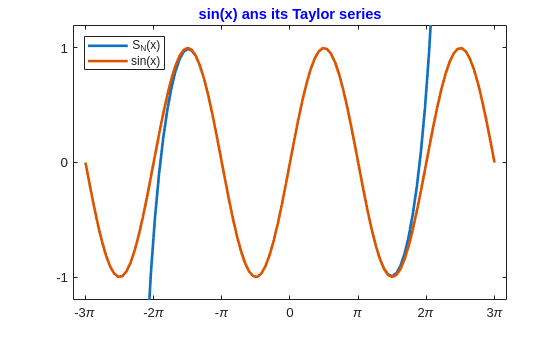

close;
L3 = 12;
x3 = linspace(-3*pi,3*pi,101);
y3 = zeros(L3+1,length(x3));
y3(1,:) = x3;
for k=2:L3+1
    y3(k,:)=y3(k-1,:)+power(-1,k-1)*power(x3,2*k-1)/factorial(2*k-1);    
end

K =6 ;
plot(x3,y3(K+1,:),x3,sin(x3),'LineWidth',2)
    ylim([-1.2 1.2])
    title(['sin(x) ans its Taylor series'],'Color','blue','FontSize',11)
    xticks([-3*pi -2*pi -pi 0 pi 2*pi 3*pi])
    xticklabels({'-3\pi','-2\pi','-\pi','0','\pi','2\pi','3\pi'})
    yticks([-1 0 1])
    yticklabels({'-1','0','1'})
    legend('S_N(x)','sin(x)','Location','northwest')

### **3. Convergence of Riemann sums**

Let $f:[a,b] \rightarrow [m,M]$ be a real-valued bounded function on an interval $[a,b]$, that is, 

the graph of $f$ is contained in a closed rectangle $[a,b]\times[m,M]$. 

We define a Riemann sum of $f$. We introduce division of $[a,b]$


$$\Delta: a=a_0<a_1<\cdots<a_n=b, 
\quad
|\Delta|:=
\max_{i=1,\ldots,n}(a_i-a_{i-1}).$$


Pick up arbitrary$\xi_1\in[a_{i-1},a_i]$  for $i=1,\ldots,n$. Set 


$$R(\Delta)
:=
\sum_{i=1}^n
f(\xi_i)(a_i-a_{i-1}). $$


This is a Riemann sum of $f$. This depends not only on the division $\Delta$ but also the choice of $\xi_1,\ldots,\xi_n$. Note that 


$$m(b-a)
\leq
R(\Delta)
\leq
M(b-a).$$


We say that $f$ is Riemann integrable if there exists a cosntant $\alpha$ such that 


$$R(\Delta) \rightarrow \alpha 
\quad
(|\Delta| \rightarrow 0),$$


which is independent of the choices of $\Delta$ and $\xi_1,\ldots,\xi_n$. 

In this case the real number $\alpha$ is said to be the Riemann integral of $f$ on the interval $[a,b]$ and is denoted by  


$$\int_a^bf(x)dx.$$


It is wellknown that if $f \in C[a,b]$, then $f$ is uniformly continuous on $[a,b]$ and Riemann integrable on $[a,b]$. 

More generally if there exist finite numbers $b_0, b_1, \ldots, b_N \in [a,b]$ such that 

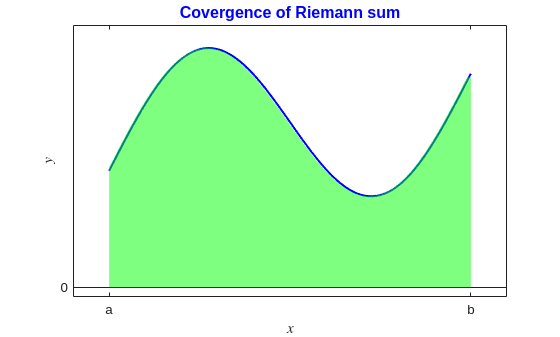

close;
n =200;

x = 0:0.005:1;
f=sin(2*pi*x)+x+1.2*ones(1,201);
g=zeros(1,201);
for j=1:199
    v=(floor(n*j/200)+ceil(n*j/200))/2/n;
    g(1,j)=sin(2*pi*v)+v+1.2;
end
g(1,200)=g(1,199);
g(1,201)=g(1,199);

figure;
plot(x, f, 'b-', 'LineWidth', 1.5); 
title('Covergence of Riemann sum','Color','blue','FontSize',12)
grid off;
xlim([-0.1 1.1])
xticks([0 1])
xticklabels({'a','b'})
ylim([-0.1 2.7])
xlabel('$x$','Interpreter','latex'); 
yticks([0])
yticklabels({'0'})
ylabel('$y$','Interpreter','latex');
hold on;
area(x, g, 'FaceColor','green', 'FaceAlpha', 0.5,'EdgeColor','none');
hold off;